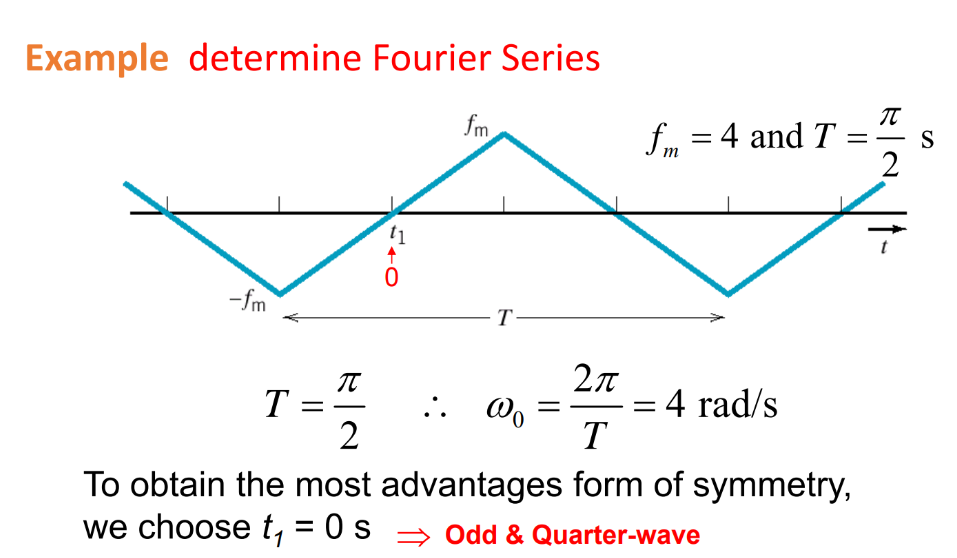

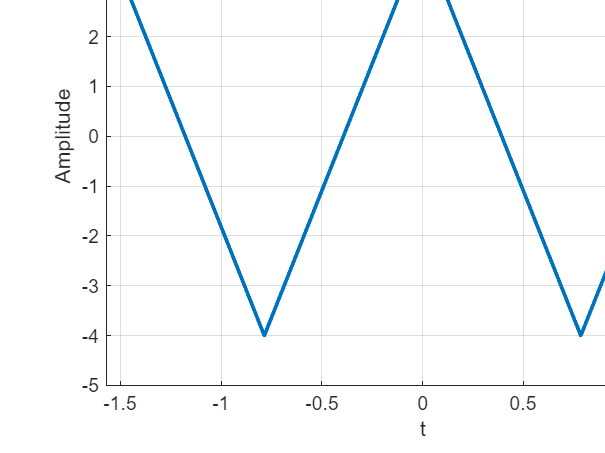

clear;clf;
T = pi/2;             
fm = 4;               
t_1 = -2*T:0.001:2*T;  
triangle_wave = -fm * sawtooth((2*pi/T)*t_1, 0.5);
plot(t_1, triangle_wave, 'LineWidth', 2);
xlabel('t'); ylabel('Amplitude');
title('Inverted Triangle Wave with Height = 4 and Period = \pi/2');
grid on;
axis([-T T -fm-1 fm+1]); 

syms t n;
assume(n,'integer');
T = pi/2;
w = 2*pi/T

w = 4

f1 = (32/pi)*t;
f2 = (-32/pi)*(t - T/4);
f = piecewise(0 <= t & t <= T/4, f1,T/4 < t & t <= T/2, f2);

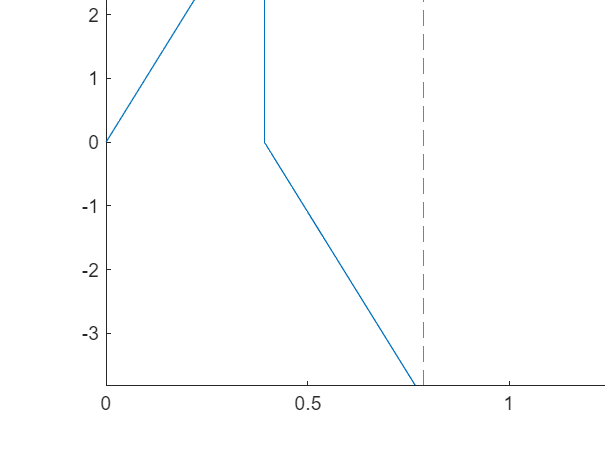

fplot(f,[0 T])

a0 = (2/T) * int(f, t, 0, T/2)

$$a0 = 0$$

an = vpa(simplify((2/T) * (int(f1 * cos(n*w*t), t, 0, T/4) + int(f2 * cos(n*w*t), t, T/4, T/2))))

$$an = \frac{0.000000000000000000000000000000024651903288156618919116517665087\,\left(65761207941142604982293558060562.0\,\cos\left(1.5707963267948966192313216916398\,n\right)+51648731939771095008619108808747.0\,n\,\sin\left(1.5707963267948966192313216916398\,n\right)-65761207941142604982293558060562.0\,{\cos\left(1.5707963267948966192313216916398\,n\right)}^{2}-103297463879542190017238217617490.0\,n\,\cos\left(1.5707963267948966192313216916398\,n\right)\,\sin\left(1.5707963267948966192313216916398\,n\right)\right)}{n^{2}}$$

bn = ((simplify(8/T*int(f1*sin(n*w*t),t,0,T/4))))

$$bn = \frac{32880603970571302491146779030281\,\left(\sin\left(\frac{\pi \,n}{2}\right)-\frac{\pi \,n\,\cos\left(\frac{\pi \,n}{2}\right)}{2}\right)}{10141204801825835211973625643008\,n^{2}}$$

del = 32880603970571302491146779030281*(pi*n*cos(pi*n/2)/2)/(10141204801825835211973625643008*n^2);

**Plot** **graph**

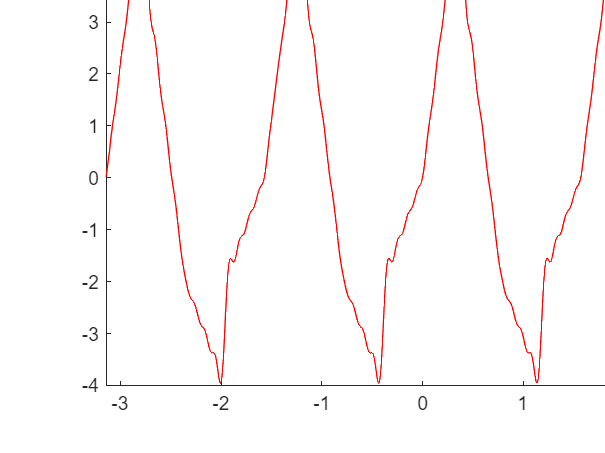

bn_sim = bn + del;
harm = 15;
f0 = an*cos(n*w*t)+bn_sim*sin(n*w*t);
fx = a0/2 + symsum(f0,n,1,harm);
fplot(fx, [-pi pi], 'r');